# HW 2 - Matlab Exercise 2

Module 2 consists of 8 sections. loading data as we did before is where we begin

data = load('../HMP_Dataset/Climb_stairs/Accelerometer-2011-03-24-10-24-39-climb_stairs-f1.txt')

data =      5    39    34
     2    41    34
     5    39    34
    12    38    34
     9    38    30
    10    36    29
    10    36    30
    12    36    30
    16    36    29
    16    37    30


% loading in the data from the csv matrix
x = data(:,1);
y = data(:,2);
z = data(:,3);


## Combining of signal

can be done with an anon function

S = @(a, b, c) (sqrt(a.^2 + b.^2 + c.^2 ))

S = function_handle with value:
    @(a,b,c)(sqrt(a.^2+b.^2+c.^2))


with this we can convert the signal for computing the energy of it.


$$E=\int_{-\infty }^{\infty } |S|^2 \mathrm{dt}$$


We are in a discrete environment, so we need the following.


$$E=\sum_{-\infty }^{\infty } |S|^2$$


matlabs sum function can do this across the vector and we can pass in the squared magnitude

E = sum(mag_squared)

## 2 combine and calculate energy

sig_S = S(x, y, z)'

sig_S =    51.9808   53.3010   51.9808   52.3832   49.2443   47.2969   47.9166   48.3735   48.9183   50.2494   49.5177   50.5767   50.9215   50.8527   50.1298   52.0288   52.3546   53.1037   52.9717   52.3927   52.0577   52.2015   49.7695   49.8197   50.8035   47.6760   50.8822   51.0882   49.4065   49.1732   48.0521   52.0192   52.6688   54.6717   53.6936   52.3355   53.3385   53.3667   52.0384   53.5257   52.3259   54.2402   53.0000   53.0377   52.1632   53.1695   49.7695   53.1507   51.0000   52.2781


mag_squared = abs(sig_S).^2 

mag_squared = 1.0e+03 *

    2.7020    2.8410    2.7020    2.7440    2.4250    2.2370    2.2960    2.3400    2.3930    2.5250    2.4520    2.5580    2.5930    2.5860    2.5130    2.7070    2.7410    2.8200    2.8060    2.7450    2.7100    2.7250    2.4770    2.4820    2.5810    2.2730    2.5890    2.6100    2.4410    2.4180    2.3090    2.7060    2.7740    2.9890    2.8830    2.7390    2.8450    2.8480    2.7080    2.8650    2.7380    2.9420    2.8090    2.8130    2.7210    2.8270    2.4770    2.8250    2.6010    2.7330


energy_S = sum(mag_squared,"all","omitmissing","double")

ans = 707770

The energy of S is obtained.

## 3 Implementation of moving average

avg_vec = [1 1 1]

avg_vec =      1     1     1


conv_S = conv(x,avg_vec)./length(avg_vec)

conv_S =     1.6667
    2.3333
    4.0000
    6.3333
    8.6667
   10.3333
    9.6667
   10.6667
   12.6667
   14.6667


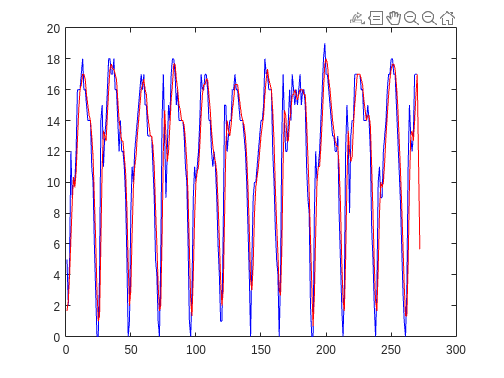

plot(1:1:length(x),x,'b',1:1:length(conv_S),conv_S,'r')

function a = convert(data)
g = 9.8; % as in m/s^2
a = -1.5*g + 3*g*(data/63);
end